tic
f1 = @(x) exp(-x.^2);

datx = -3:1:3;
x = -3:0.01:3;
daty = f1(datx);
P5 = Newtons_divided_difference(x, datx,daty);
P5 = P5'

P5 =     0.0001
    0.0261
    0.0510
    0.0747
    0.0973
    0.1189
    0.1394
    0.1589
    0.1774
    0.1949



toc

Elapsed time is 0.279787 seconds.


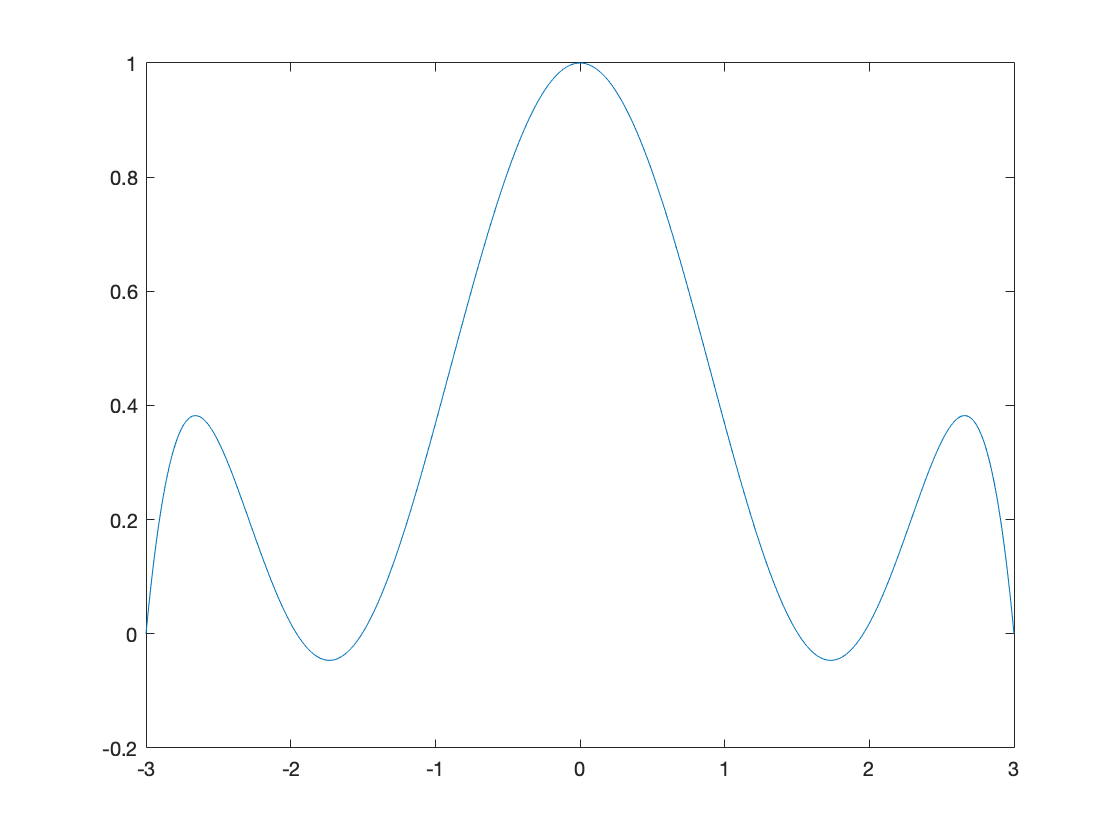

plot(x,P5)

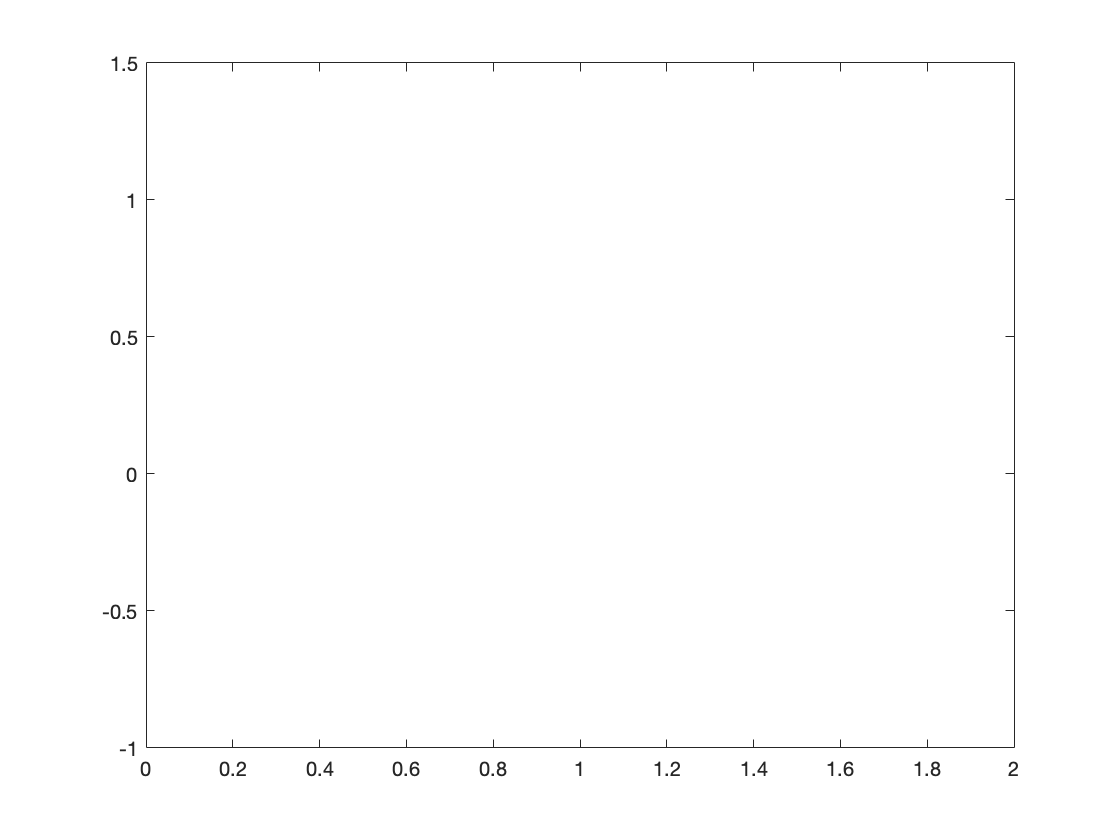

% plot(toc)

function y = Newtons_divided_difference(x, datx, daty)
n = size(datx,1);

if n == 1
    n = size(datx,2);
end


for i = 1:n
    F(i,1) = daty(i);
end

for i = 2:n
    for j = 2:i
        
        F(i,j) = (F(i,j-1) - F(i-1,j-1)) / (datx(i)-datx(i-j+1));
    end
end

m = size(x,2);

for j = 1:m
    y(j) = F(n,n);
    
    for i = n-1:-1:1
        y(j) = y(j)*(x(j)-datx(i)) + F(i,i);
    end
end

end